# Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

Check that MATLAB can recognize the Python installation. Use `pyversion` if you are using a MATLAB version prior to R2019b.

% pyversion()
pyenv

ans =   PythonEnvironment with properties:

          Version: "3.8"
       Executable: "C:\Program Files\Python38\python.EXE"
          Library: "C:\Program Files\Python38\python38.dll"
             Home: "C:\Program Files\Python38"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "2228"
      ProcessName: "MATLAB"


Test a simple function.

py.math.sqrt(450)

ans = 21.2132

Pass arguments using pyargs.

% py.textwrap.wrap("Hello world!",pyargs('width',2))   % errors
py.textwrap.wrap("Hello world!",pyargs('width',int8(2)))

ans =   Python list with values:

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

    Use string, double or cell function to convert to a MATLAB array.


## Read weather data using Python module 

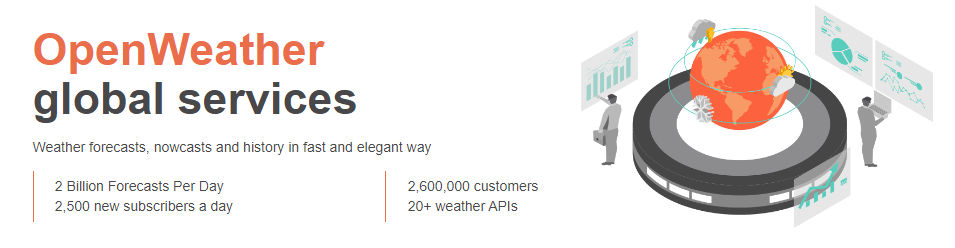

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the weather.py module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("Mexico+City","MX",apikey.Key)

jsonData =   Python dict with no properties.

    {'coord': {'lon': -99.1277, 'lat': 19.4285}, 'weather': [{'id': 200, 'main': 'Thunderstorm', 'description': 'thunderstorm with light rain', 'icon': '11d'}, {'id': 500, 'main': 'Rain', 'description': 'light rain', 'icon': '10d'}], 'base': 'stations', 'main': {'temp': 69.4, 'feels_like': 67.93, 'temp_min': 67.93, 'temp_max': 70.95, 'pressure': 1017, 'humidity': 40}, 'visibility': 10000, 'wind': {'speed': 20, 'deg': 60}, 'rain': {'1h': 0.11}, 'clouds': {'all': 100}, 'dt': 1650933157, 'sys': {'type': 2, 'id': 47729, 'country': 'MX', 'sunrise': 1650888695, 'sunset': 1650934620}, 'timezone': -18000, 'id': 3530597, 'name': 'Mexico City', 'cod': 200}


Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 69.4, 'feels_like': 67.93, 'temp_min': 67.93, 'temp_max': 70.95, 'pressure': 1017, 'humidity': 40, 'speed': 20, 'deg': 60, 'lon': -99.1277, 'lat': 19.4285, 'city': 'Mexico City', 'current_time': '2022-04-25 19:35:05.118227'}


## Preprocess data 

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 69.4000
      feels_like: 67.9300
        temp_min: 67.9300
        temp_max: 70.9500
        pressure: [1×1 py.int]
        humidity: [1×1 py.int]
           speed: [1×1 py.int]
             deg: [1×1 py.int]
             lon: -99.1277
             lat: 19.4285
            city: [1×11 py.str]
    current_time: [1×26 py.str]


Convert the remaining python types to the desired MATLAB data types.

double(data.pressure)

ans = 1017

Perform the remaining conversions using the function below. 

convertData(data)

## Handle timeseries with the weather forecast

Now let's look at the weather forecast for this week in Boston!

jsonData = py.weather.get_forecast("Boston","US",apikey.Key);
forecastData = py.weather.parse_forecast_json(jsonData);
forecast = struct(forecastData)

forecast = struct with fields:
    current_time: [1×40 py.list]
            temp: [1×40 py.list]
             deg: [1×40 py.list]
           speed: [1×40 py.list]
        humidity: [1×40 py.list]
        pressure: [1×40 py.list]


The type of data returned by the parsed forecast date is a **Python list**:

forecast.temp

ans =   Python list with values:

    [47.77, 45.93, 43.95, 48.58, 57.88, 59.99, 58.1, 53.76, 52.7, 52.11, 50.79, 47.95, 55.51, 59.47, 55.27, 45.88, 41.79, 39.85, 36.91, 40.12, 48.15, 52.54, 50.74, 46.18, 44.06, 41.25, 40.12, 41.02, 47.55, 50.56, 50.77, 47.26, 44.82, 42.71, 41.45, 43.47, 46.9, 49.69, 51.26, 48.38]

    Use string, double or cell function to convert to a MATLAB array.


It can be converted to a matrix of doubles:

% tempForecast = double(forecast.temp)          % from an array
tempForecast = cell2mat(cell(forecast.temp))    % from a list

tempForecast =    47.7700   45.9300   43.9500   48.5800   57.8800   59.9900   58.1000   53.7600   52.7000   52.1100   50.7900   47.9500   55.5100   59.4700   55.2700   45.8800   41.7900   39.8500   36.9100   40.1200   48.1500   52.5400   50.7400   46.1800   44.0600   41.2500   40.1200   41.0200   47.5500   50.5600   50.7700   47.2600   44.8200   42.7100   41.4500   43.4700   46.9000   49.6900   51.2600   48.3800


Transform **timestamp list** from Python in **MATLAB datetime**:

foreTime = cell(forecast.current_time)

foreTime = 1×40 cell array
    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}


T = cellfun(@string,foreTime)

T = 1×40 string array
    "2022-04-26 03:00:00"    "2022-04-26 06:00:00"    "2022-04-26 09:00:00"    "2022-04-26 12:00:00"    "2022-04-26 15:00:00"    "2022-04-26 18:00:00"    "2022-04-26 21:00:00"    "2022-04-27 00:00:00"    "2022-04-27 03:00:00"    "2022-04-27 06:00:00"    "2022-04-27 09:00:00"    "2022-04-27 12:00:00"    "2022-04-27 15:00:00"    "2022-04-27 18:00:00"    "2022-04-27 21:00:00"    "2022-04-28 00:00:00"    "2022-04-28 03:00:00"    "2022-04-28 06:00:00"    "2022-04-28 09:00:00"    "2022-04-28 12:00:00"    "2022-04-28 15:00:00"    "2022-04-28 18:00:00"    "2022-04-28 21:00:00"    "2022-04-29 00:00:00"    "2022-04-29 03:00:00"    "2022-04-29 06:00:00"    "2022-04-29 09:00:00"    "2022-04-29 12:00:00"    "2022-04-29 15:00:00"    "2022-04-29 18:00:00"    "2022-04-29 21:00:00"    "2022-04-30 00:00:00"    "2022-04-30 03:00:00"    "2022-04-30 06:00:00"    "2022-04-30 09:00:00"    "2022-04-30 12:00:00"    "2022-04-30 15:00:00"    "2022-04-30 18:00:00"    "2022-04-30 21:00:00"   

Convert T in datetime

time = datetime(T)

time = 1×40 datetime array
   26-Apr-2022 03:00:00   26-Apr-2022 06:00:00   26-Apr-2022 09:00:00   26-Apr-2022 12:00:00   26-Apr-2022 15:00:00   26-Apr-2022 18:00:00   26-Apr-2022 21:00:00   27-Apr-2022 00:00:00   27-Apr-2022 03:00:00   27-Apr-2022 06:00:00   27-Apr-2022 09:00:00   27-Apr-2022 12:00:00   27-Apr-2022 15:00:00   27-Apr-2022 18:00:00   27-Apr-2022 21:00:00   28-Apr-2022 00:00:00   28-Apr-2022 03:00:00   28-Apr-2022 06:00:00   28-Apr-2022 09:00:00   28-Apr-2022 12:00:00   28-Apr-2022 15:00:00   28-Apr-2022 18:00:00   28-Apr-2022 21:00:00   29-Apr-2022 00:00:00   29-Apr-2022 03:00:00   29-Apr-2022 06:00:00   29-Apr-2022 09:00:00   29-Apr-2022 12:00:00   29-Apr-2022 15:00:00   29-Apr-2022 18:00:00   29-Apr-2022 21:00:00   30-Apr-2022 00:00:00   30-Apr-2022 03:00:00   30-Apr-2022 06:00:00   30-Apr-2022 09:00:00   30-Apr-2022 12:00:00   30-Apr-2022 15:00:00   30-Apr-2022 18:00:00   30-Apr-2022 21:00:00   01-May-2022 00:00:00


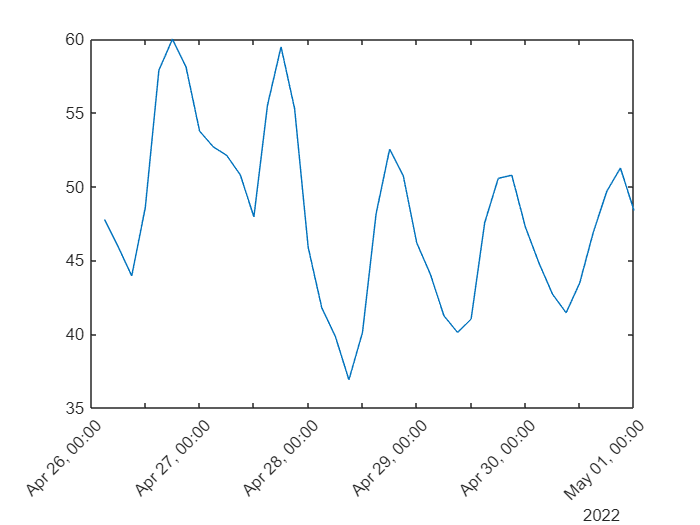

plot(time,tempForecast)
xtickangle(45)

## Preprocess data using MATLAB live task

Weather forecasts are only provided every 4 hours. We want to retime to have data interpolated every single hour.

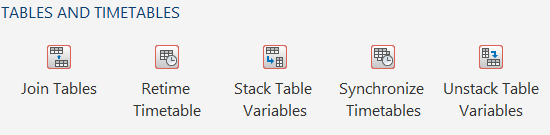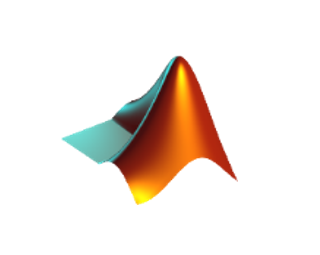

foreTemp = timetable(time',tempForecast','VariableNames',{'Temperature'})

foreTemp = 40×1 timetable
            Time            Temperature
    ____________________    ___________

    26-Apr-2022 03:00:00       47.77   
    26-Apr-2022 06:00:00       45.93   
    26-Apr-2022 09:00:00       43.95   
    26-Apr-2022 12:00:00       48.58   
    26-Apr-2022 15:00:00       57.88   
    26-Apr-2022 18:00:00       59.99   
    26-Apr-2022 21:00:00        58.1   
    27-Apr-2022 00:00:00       53.76   
    27-Apr-2022 03:00:00        52.7   
    27-Apr-2022 06:00:00       52.11   
    27-Apr-2022 09:00:00       50.79   
    27-Apr-2022 12:00:00       47.95   
    27-Apr-2022 15:00:00       55.51   
    27-Apr-2022 18:00:00       59.47   
    27-Apr-2022 21:

% Retime timetable
newTimetable = retime(foreTemp,'regular','spline','TimeStep',hours(1))

newTimetable = 118×1 timetable
            Time            Temperature
    ____________________    ___________

    26-Apr-2022 03:00:00       47.77   
    26-Apr-2022 04:00:00       47.67   
    26-Apr-2022 05:00:00      46.957   
    26-Apr-2022 06:00:00       45.93   
    26-Apr-2022 07:00:00      44.888   
    26-Apr-2022 08:00:00      44.128   
    26-Apr-2022 09:00:00       43.95   
    26-Apr-2022 10:00:00      44.603   
    26-Apr-2022 11:00:00      46.144   
    26-Apr-2022 12:00:00       48.58   
    26-Apr-2022 13:00:00      51.791   
    26-Apr-2022 14:00:00      55.144   
    26-Apr-2022 15:00:00       57.88   
    26-Apr-2022 16:00:00      59.432   
    26-Apr-202

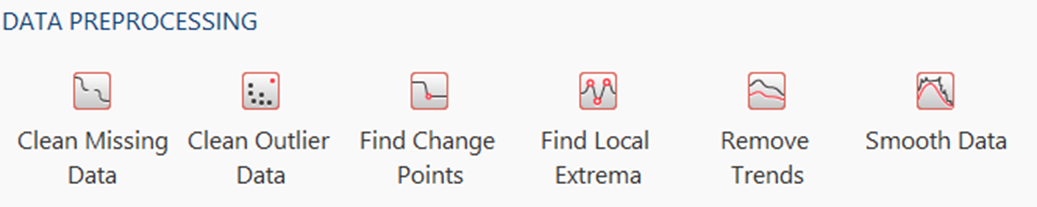

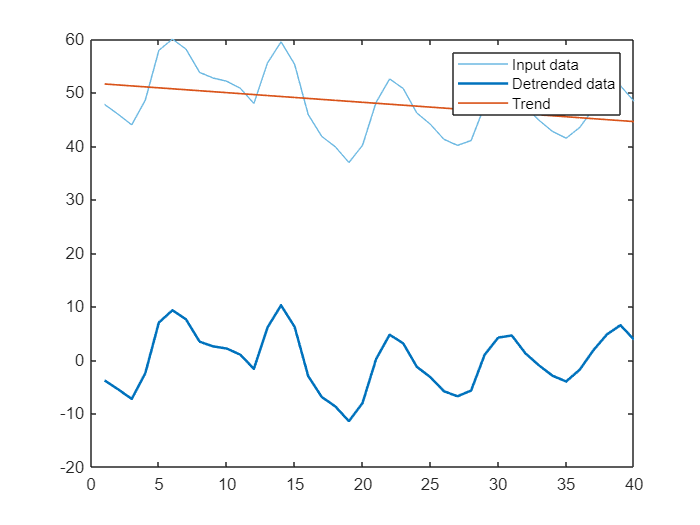

% Remove trend from data
detrendedData = detrend(tempForecast);

% Display results
clf
plot(tempForecast,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(detrendedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(tempForecast-detrendedData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

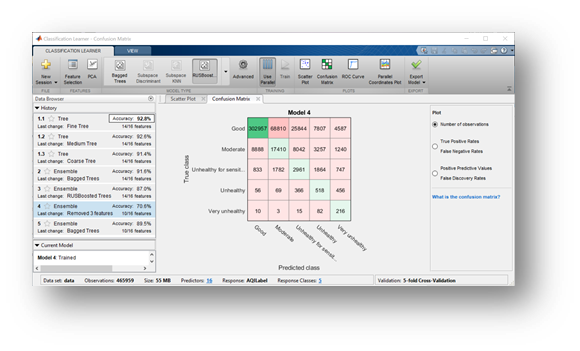

Use a function (`prepData.m`) to convert and prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

currentData = 1×12 table
         DateLocal            city        StateName        T       P       DP     RH    WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _____________    _____    ____    ____    __    _______    _______    ____    __    __

    25-Apr-2022 19:09:24    "Boston"    Massachusetts    48.24    1024    37.8    71      120       11.5      2022    4     25


Use the model to predict the air quality for the new weather data.

'*airQualModel.mat*' is a pre-trained Bagged Classification Tree/ "Random Forest" classification network. The network was trained using a large data set stored on a local HDFS cluster (~1TB of historical weather data) and required the use of the "tall" MATLAB datatype.  The model was saved as a *.mat file for use in predicting air quality in this demonstration. 

load airQualModel 

airQual = predict(model,currentData)

airQual = categorical
     Good 


## Share prediction code

Create a function with these steps to be called in the Python environment.

edit("predictAirQual.m")

See `CallMATLABfromPython.ipynb`

## Reload Python module

Reload *weather.py *after modifications:

clear classes

mod = py.importlib.import_module('weather'); 
py.importlib.reload(mod); 

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/releases/R2015b/matlab/matlab_external/call-modified-python-module.html)

**Helper Functions**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end

Subsequential calls of the `weather.py` functions in a single MATLAB function:

function [time,tempForecast] = callWeatherFromPython(city,apikey)
    switch city
        case "Boston" 
            country = "US";
        case "Paris"
            country = "France";
        case "Moscow"
            country = "Russia";
    end
    jsonData = py.weather.get_forecast(city,country,apikey);
    forecastData = py.weather.parse_forecast_json(jsonData);
    forecast = struct(forecastData);
    tempForecast = double(forecast.temp);
    foreTime = cell(forecast.current_time);
    T = cellfun(@string,foreTime);
    time = datetime(T);
end